# 'axis' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create *camera* object and put it in separate include file to save rendering time in future

pl.include_begin('camera');
    pl.camera('angle', 35, 'location', [12 12 8], 'look_at', [0 0 0.5], 'type', 'perspective');
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time in future

pl.include_begin('lights');
    pl.light('location', [10 10 7],     'color', [3 3 3], 'shadowless', true);
    pl.light('location', [-10 10 30],   'color', [3 3 3], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Default axis

pl.scene_begin('scene_file', 'axis.pov', 'image_file', 'axis.png');
    pl.include("camera");
    pl.include("lights");

    pl.axis('length', [5 5 4]);
pl.scene_end();

#### Render and display

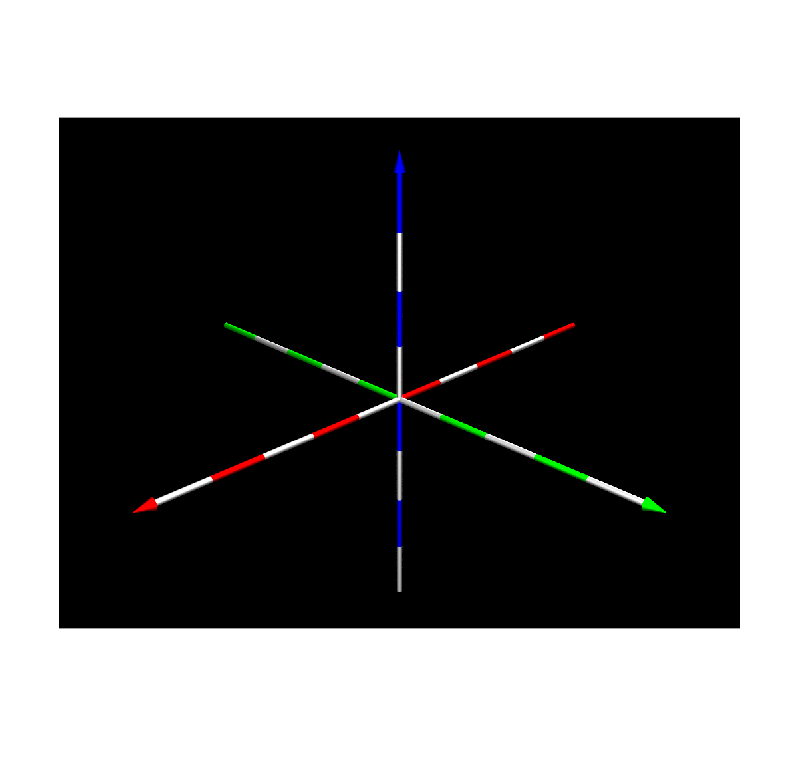

image = pl.render();
imshow(image);

#### **Axis of custom color and thickness  **


pl.scene_begin('scene_file', 'axis_colored.pov', 'image_file', 'axis_colored.png');
    pl.include("camera");
    pl.include("lights");
    
    % Texture
    tex_gray   = pl.declare("tex_gray",   pl.texture('pigment', [0.2 0.2 0.2]));
    tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [0.6 0.6 0.0]));
    tex_pink   = pl.declare("tex_pink",   pl.texture('pigment', [0.8 0.2 0.3]*1.2));
    tex_green  = pl.declare("tex_green",  pl.texture('pigment', [0.0 0.3 0.0]));

    pl.axis('length', [5 5 4], 'radius', 0.07, 'tex_common', tex_gray, 'tex_x', tex_yellow, 'tex_y', tex_pink, 'tex_z', tex_green);
pl.scene_end();

#### Render and display

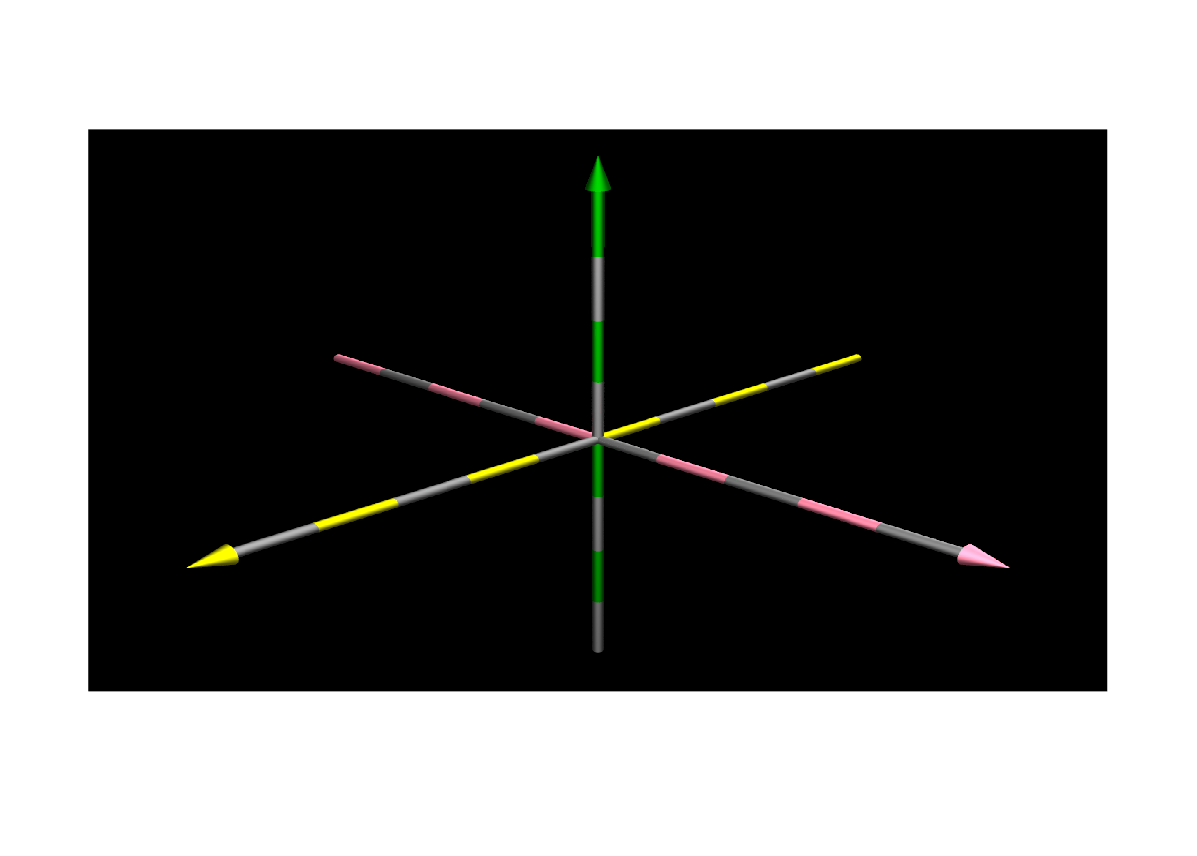

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 3.565958 seconds.
